## Project 1

### Create imageData instances

% setting the directory
wd = '/home/ginevracoal/MEGA/Università/DSSC/semester_3/ComputerVision-PatternRecognition/zhang-camera-calibration/src';
cd(wd)

%creating imagedata instances
[imageData, iimage] = create_imagedata(wd);

% perform Zhang camera calibration
[imageData, K] = complete_camera_calibration(imageData, iimage);

% perform  radial distortion compensation on a chosen image
idx = 1

idx = 1

rep_error = 83.4870

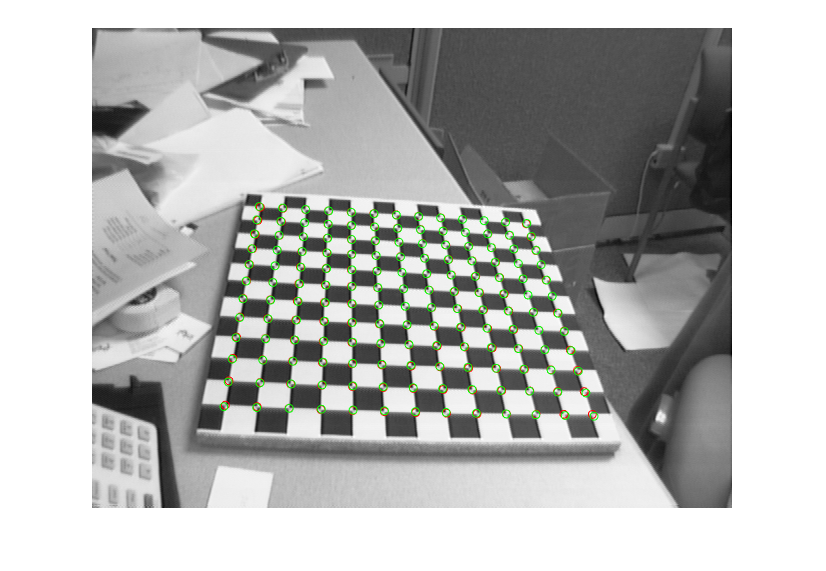

rep_error = 0.0016

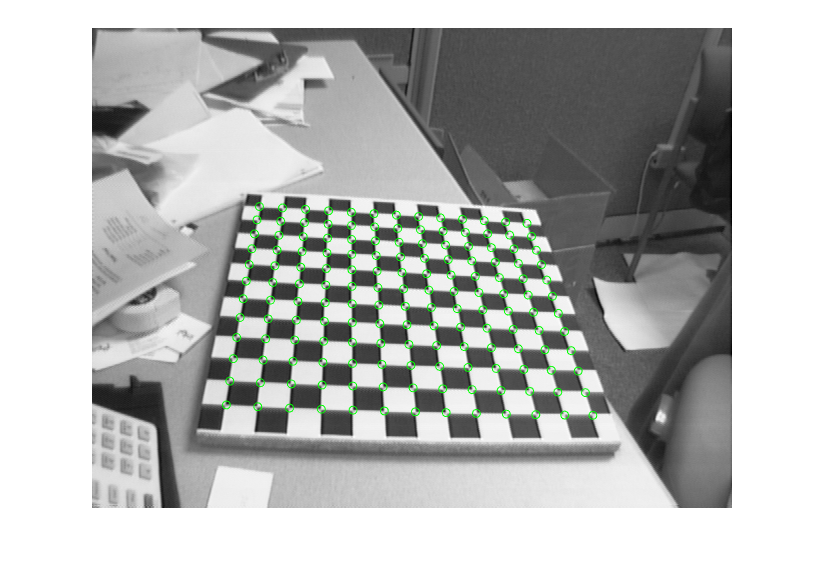

[imageData] = iterative_radial_compensation(imageData, iimage, K, idx);

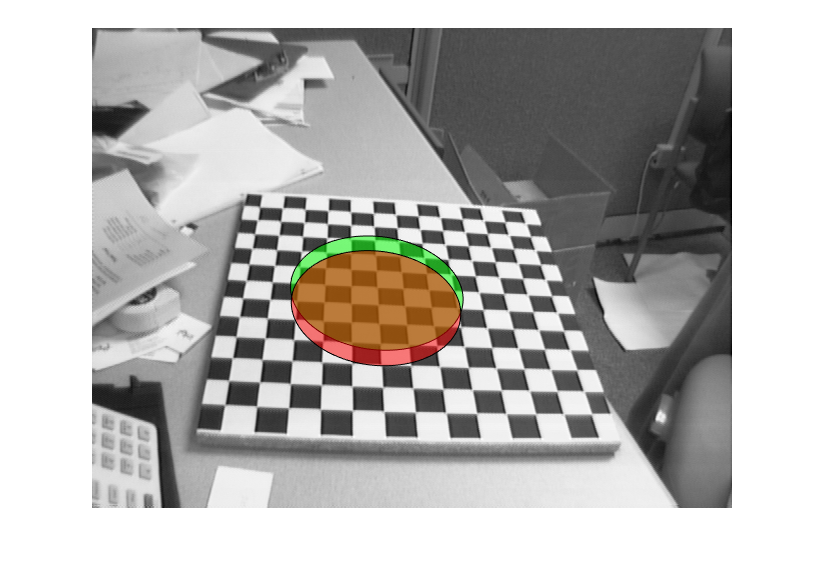

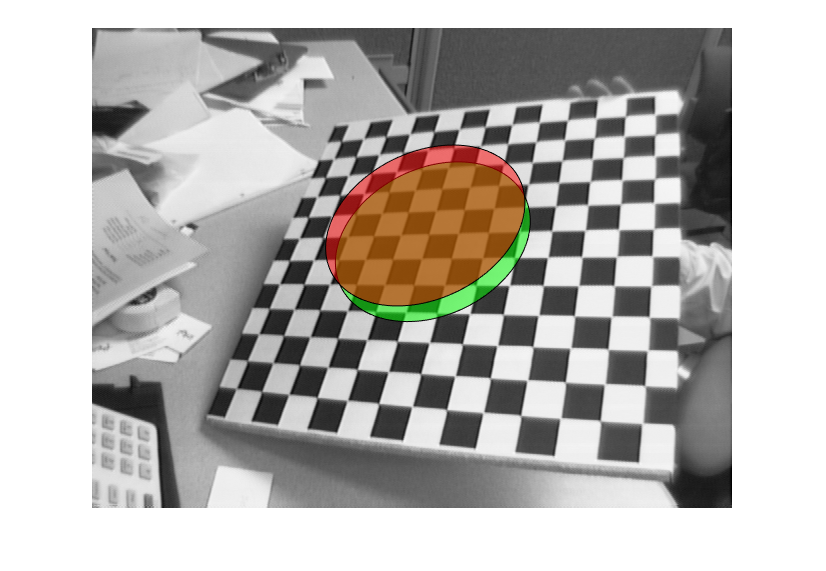

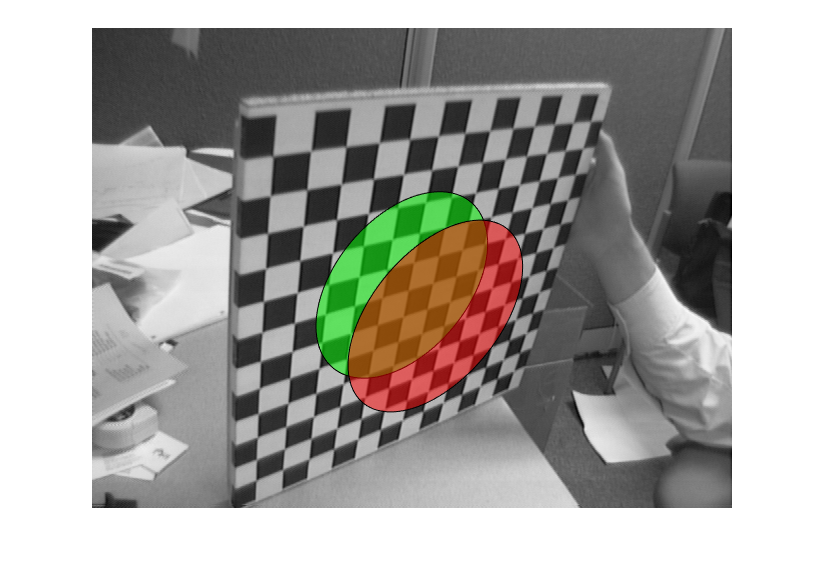

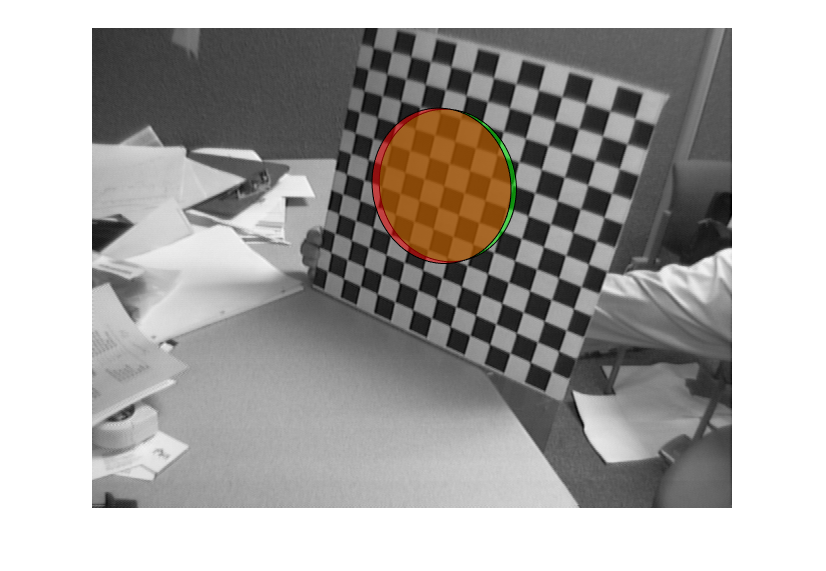

% superimpose a 3d object to each image

for ii=1:length(iimage)
    figure
    imshow(imageData(ii).I)
    P = K*[imageData(ii).R imageData(ii).t]; % 3x4
   
    hold on % superimpose something
    
    vtheta=0:0.01:2*pi; % take equally spaced points
    centerX=150; % these are mm of course
    centerY=150;
    radius=100;
    % discretize the circle by taking some coordinates on it
    vX=centerX+radius*cos(vtheta);
    vY=centerY+radius*sin(vtheta);
    
    % projections from plane z=0
    vZ=zeros(1,length(vtheta));
    homogeneous = [vX; vY; vZ; ones(1,length(vtheta))];
    proj_hom=P*homogeneous;
    proj=[ proj_hom(1,:)./proj_hom(3,:); ...
           proj_hom(2,:)./proj_hom(3,:)];
    
    f=fill(proj(1,:),proj(2,:),'g');
    set(f,'facealpha',.5)
    
    % projections from plane z!=0
    hold on
   
    vZ=repmat(5e6,1,length(vtheta));
    new_homogeneous = [vX; vY; vZ; ones(1,length(vtheta))];
    new_proj_hom = P*new_homogeneous;
    new_proj = [new_proj_hom(1,:)./new_proj_hom(3,:);...
                new_proj_hom(2,:)./new_proj_hom(3,:)];
                
    f2=fill(new_proj(1,:),new_proj(2,:),'r');
    set(f2,'facealpha',.5)
end